# Closeness and Betweenness of Minnesota Roads

Load the data in `minnesota.mat`, which contains a graph object `G` representing the network of roads in Minnesota. The graph nodes have *xy* coordinates contained in the `XCoord` and `YCoord` variables of the `G.Nodes` table. 

load minnesota.mat
xy = [G.Nodes.XCoord G.Nodes.YCoord];

Add edge weights to the graph that roughly correspond to the length of the roads, calculated using the Euclidean distance between the *xy* coordinates of the end nodes of each edge.

[s,t] = findedge(G);
G.Edges.Weight = hypot(xy(s,1)-xy(t,1), xy(s,2)-xy(t,2));

Plot the graph using the *xy* coordinates for the nodes.

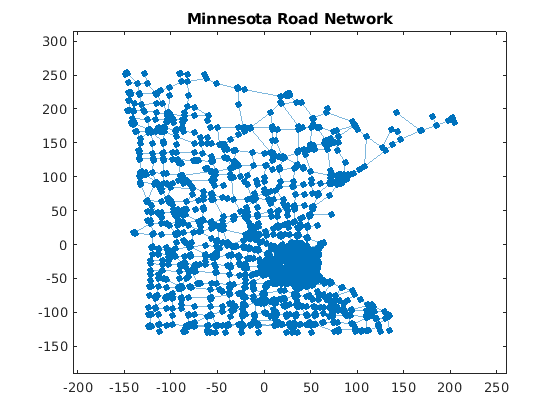

p = plot(G,'XData',xy(:,1),'YData',xy(:,2),'MarkerSize',5);
title('Minnesota Road Network')

Compute the closeness centrality of each node. Scale the node color `NodeCData` to be proportional to the centrality score.

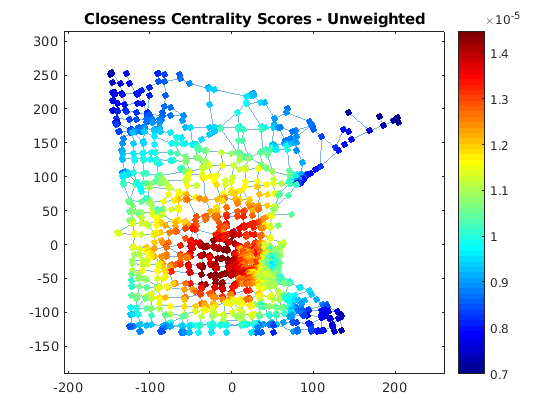

ucc = centrality(G,'closeness');
p.NodeCData = ucc;
colormap jet
colorbar
title('Closeness Centrality Scores - Unweighted')

Also compute the weighted closeness centrality score, using the edge weights as the cost of traversing each edge. Using the road lengths as edge weights improves the score quality, since distances are now measured as the sum of the lengths of all traveled edges, rather than the number of edges traveled.

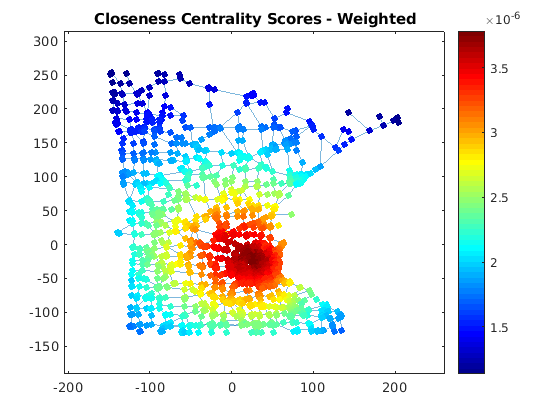

wcc = centrality(G,'closeness','Cost',G.Edges.Weight);
p.NodeCData = wcc;
title('Closeness Centrality Scores - Weighted')

Compute the weighted betweenness centrality scores for the graph to determine the roads most often found on the shortest path between two nodes. Normalize the centrality scores with the factor $\frac{(n-2)(n-1)}{2}$ so that the score represents the probability that a traveler along a shortest path between two random nodes will travel through a given node. The plot indicates that there are a few very important roads leading into and out of the city.

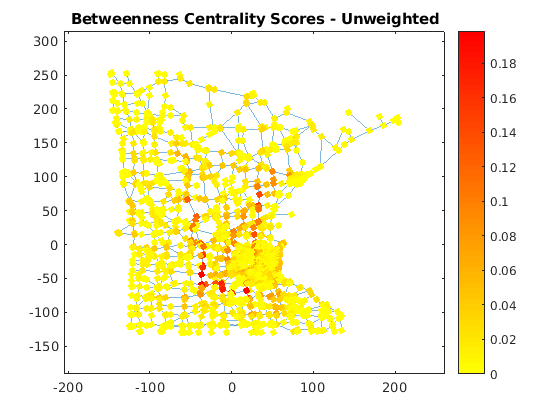

%wbc = centrality(G,'betweenness','Cost',G.Edges.Weight);
wbc = centrality(G,'betweenness');
n = numnodes(G);
p.NodeCData = 2*wbc./((n-2)*(n-1));
colormap(flip(autumn,1));
title('Betweenness Centrality Scores - Unweighted')

Random Walk Centrality: Hayato

wcc = RW_centrality_rand_install(G.adjacency,3,n);
p.NodeCData = wcc;
title('Short Random Walk Centrality Scores - Unweighted')